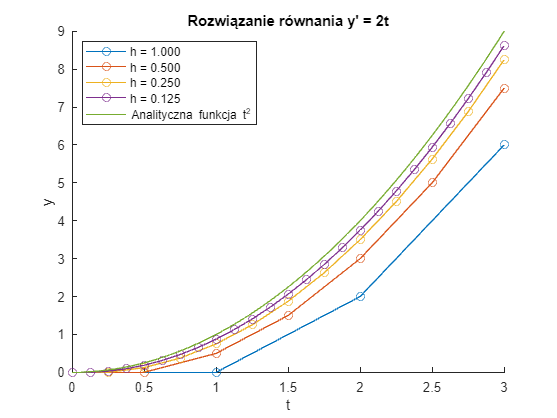

clear;
close;
%Zadanie 1
h = [1,0.5,0.25,0.125];
f = @(t) 2*t;
N = 3;
figure
hold on
for i = h
    t = 0:i:N;
    y(1) = 0;
    for j = 1:N/i
        dy = f(t(j));
        y(j+1) = y(j) +dy*i;
    end
    plot(t,y,"o-", "DisplayName",sprintf("h = %.3f",i))
end
fplot(@(t) t.^2,[0,3],"DisplayName","Analityczna funkcja t^2")
legend("Location","northwest")
title("Rozwiązanie równania y' = 2t")
xlabel("t")
ylabel('y')

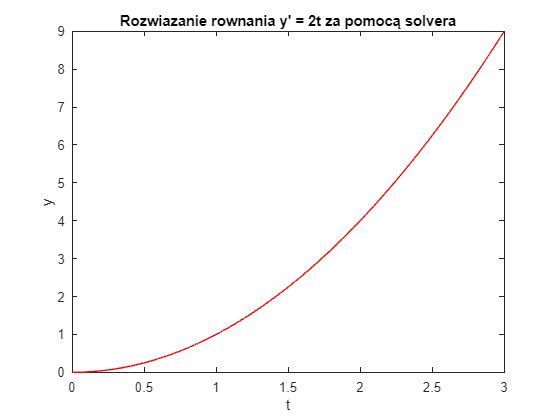

%zadanie 2

fun = @(t,y) 2*t;
[t,y] = ode45(fun,[0,3],0);
figure
plot(t,y,'r')
title("Rozwiazanie rownania y' = 2t za pomocą solvera")
xlabel("t")
ylabel('y')

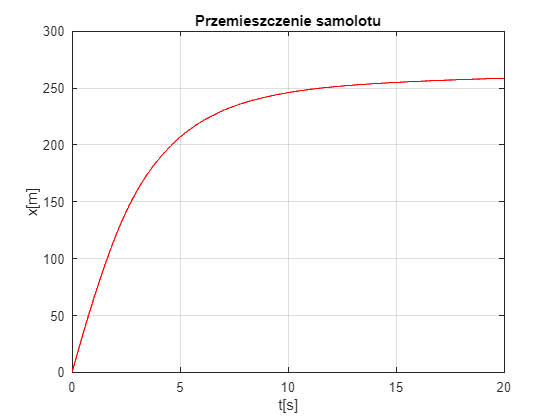

%zadanie 3

global w3
options = odeset('OutputFcn',@hamownik_out,'Refine',1);
[T,Y] = ode45(@hamownik,[0 20],[0 67 0 0 0 0],options);

figure
plot(T,Y(:,1),'r')
title("Przemieszczenie samolotu")
xlabel("t[s]"); ylabel("x[m]"); grid on;

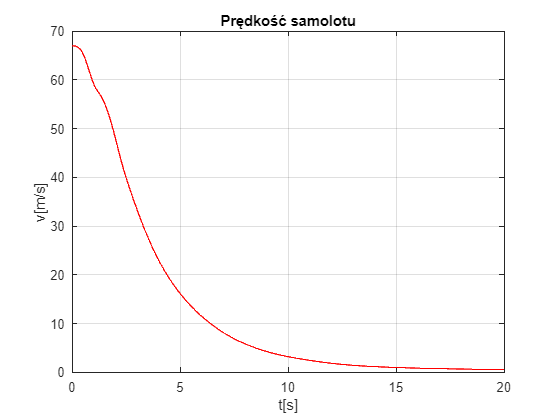


figure
plot(T,Y(:,2),'r')
title("Prędkość samolotu")
xlabel("t[s]"); ylabel("v[m/s]"); grid on;

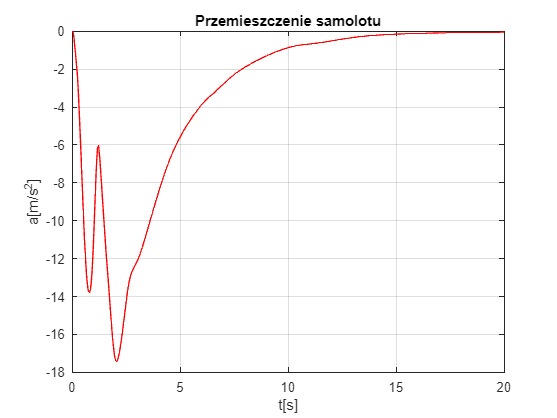


figure
plot(T,w3,'r')
title("Przemieszczenie samolotu")
xlabel("t[s]"); ylabel("a[m/s^2]"); grid on;